# Generate Images Using Diffusion

This example shows how to generate new images using a denoising diffusion probabilistic model (DDPM) [1]. 

A diffusion model learns to generate images through a training process that involves two main steps:

- Forward diffusion — The model takes a clear image as input and iteratively adds noise to it. The model learns to capture the statistical patterns and dependencies within the data by observing the changes in the image as it adds noise.

- Reverse diffusion — The model aims to reconstruct the original clear image from the noisy version. As the model knows the noise added at each step by the forward diffusion process, it can reverse the diffusion process iteratively. The model predicts the added noise and subtracts it from the image, gradually removing the noise and restoring the original clear image. The model learns to denoise the image by predicting the noise accurately.

Once you have trained the network, you can use it to generate new images by starting from random noise and successively removing the added noise that the network predicts.

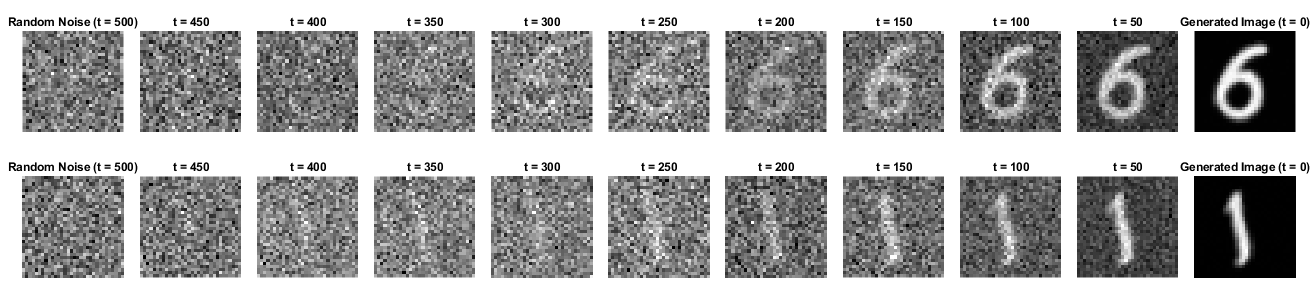

## Load Data

Load the digits data as an image datastore using the `imageDatastore` function and specify the folder containing the image data.

unzip("DigitsData.zip");
dataFolder = "DigitsData";
imds = imageDatastore(dataFolder,IncludeSubfolders=true);

Use an augmented image datastore to resize the images to have size 32-by-32 pixels.

imgSize = [32 32];
audsImds = augmentedImageDatastore(imgSize,imds);

## Forward Diffusion Process

The forward diffusion (noising) process iteratively adds Gaussian noise to an image until the result is indistinguishable from random noise. At each noising step $t$, add Gaussian noise $\varepsilon$ using the equation:


$$x_{t + 1} = \sqrt{1 - \beta_t} x_t + \sqrt{\beta_t} \varepsilon,$$


where $x_t
$ is the $t$th noisy image and $\beta_t$ is the variance schedule. The variance schedule defines how the model adds noise to the images. In this example, define a variance schedule of 500 steps from $\beta_\mathrm{min} = 0.0001 $to $\beta_\mathrm{max} = 0.02$ that increases linearly with $t$.

numNoiseSteps = 500;
betaMin = 1e-4;
betaMax = 0.02;
varianceSchedule = linspace(betaMin,betaMax,numNoiseSteps);

Apply the forward diffusion process on a test image. Extract a single image from the augmented image datastore and rescale it so that the pixel values are in the range `[-1 1]`.

img = read(audsImds);
img = img{1,1};
img = img{:};
img = rescale(img,-1,1);

Use the helper function `applyNoiseToImage`, defined at the end of this example, to apply increasing amounts of noise to the test image. To display the output at intermediate points, apply `numNoiseSteps` steps of noise to the image.

Starting from a clear image on the left, the diffusion process adds more noise until the final noising step where the image is indistinguishable from random noise.

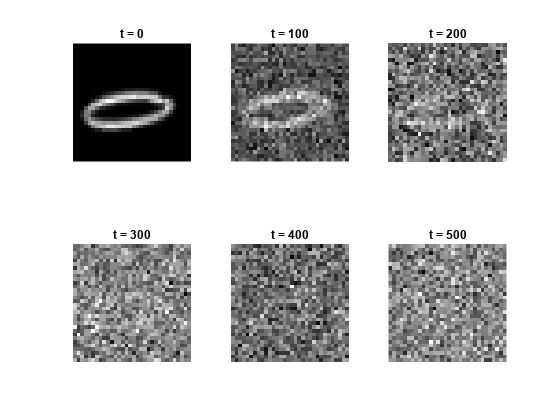

tiledlayout("flow");
nexttile
imshow(img,[])
title("t = 0");
for i = 1:5
    nexttile
    noise = randn(size(img),like=img);
    noiseStepsToApply = numNoiseSteps/5 * i;
    noisyImg = applyNoiseToImage(img,noise,noiseStepsToApply,varianceSchedule);

    % Extract the data from the dlarray.
    noisyImg = extractdata(noisyImg);
    imshow(noisyImg,[])
    title("t = " + string(noiseStepsToApply));
end

If you know the added noise at each step, you can reverse the process exactly to recreate the original clear image. Then, if you know the exact statistical distribution of the images, you can perform the reverse process for any random noise to create an image drawn from the training data distribution.

The exact statistical distribution of the dataset is too complicated to compute analytically. However, this example shows how you can train a deep learning network to approximate it. Once you have trained the network, you can use it to generate new images by starting from random noise and successively removing the added noise that the network predicts (denoising).

## Define Network

The diffusion network takes two inputs: an image input and a scalar feature input representing the number of noise steps added to the image. The network outputs a single image representing the noise that the model predicts has been added to the image.

The network architecture is based on the network used in [1]. The network is built around two types of repeating units:

- Residual blocks

- Attention blocks

The residual blocks perform convolution operations with skip connections.

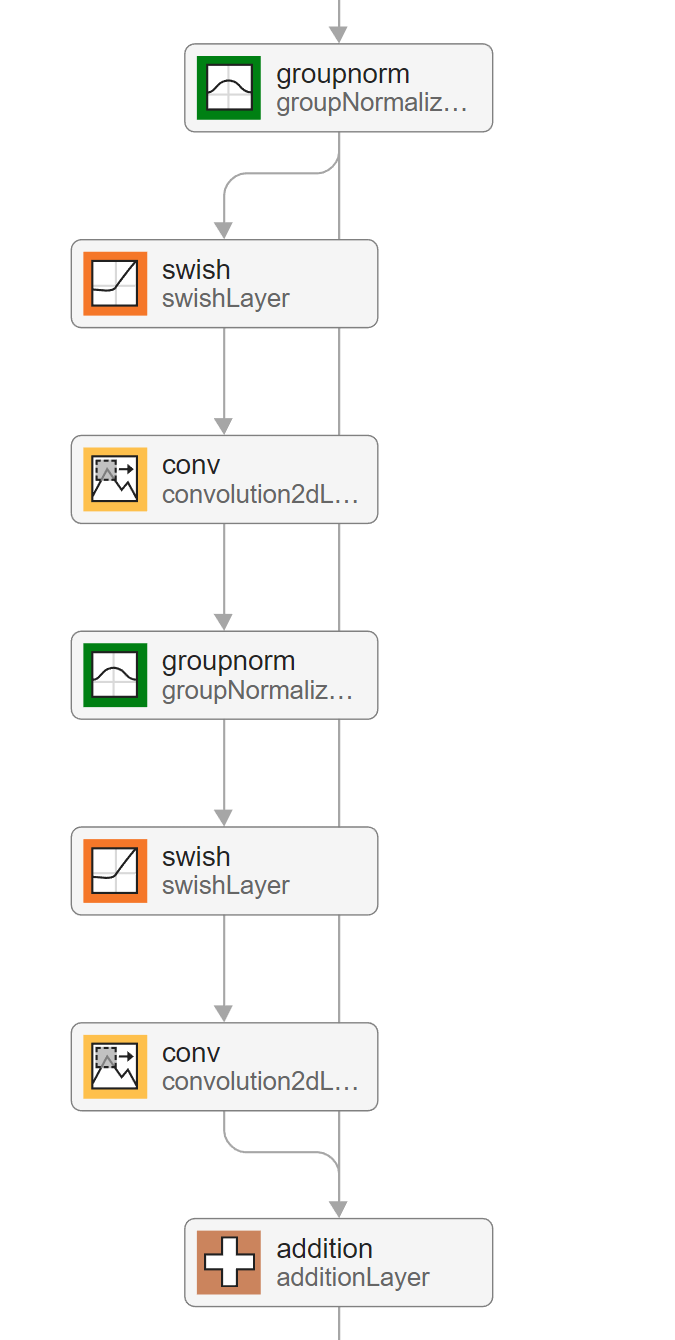

The attention blocks perform self-attention operations with skip connections.

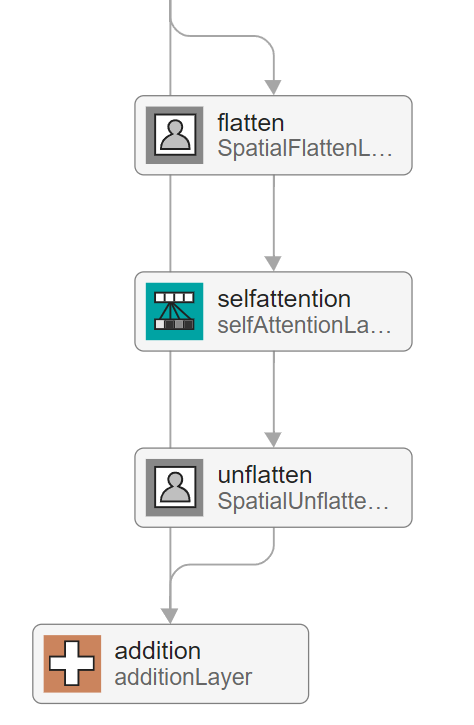

The network has an encoder-decoder structure similar to a U-Net [2]. It repeatedly downsamples an input image to a lower resolution, processes it, and then repeatedly upsamples it to the original size. The network processes the inputs using residual blocks at each resolution. At resolutions of 16-by-16 and 8-by-8 pixels, the network uses attention blocks, which contain self-attention layers, to learn correlations between parts of the input image. To use self-attention layers, the network reshapes the activations using the custom `SpatialFlattenLayer` so that they have a single spatial dimension. After applying attention, the network reshapes the activations back to 2-D images using the custom `SpatialUnflattenLayer`. Both layers are included as supporting files with this example.

The network encodes the noise step input using sinusoidal position encoding and adds it to each residual block so that the network can learn to distinguish between different amounts of added noise. The network combines the output of each downsampling residual block with the output of its complementary upsampling residual block using depth concatenation.

To create the diffusion network, use the function `createDiffusionNetwork`, attached to this example as a supporting file. This example uses grayscale images, which have one color channel. To train a network on RGB images, change the `numInputChannels` value to 3.

numInputChannels = 1;
net = createDiffusionNetwork(numInputChannels)

net =   dlnetwork with properties:

         Layers: [205×1 nnet.cnn.layer.Layer]
    Connections: [244×2 table]
     Learnables: [274×3 table]
          State: [0×3 table]
     InputNames: {'imageinput'  'input'}
    OutputNames: {'conv_29'}
    Initialized: 1

  View summary with summary.


The full diffusion network has 205 layers. To see the full network architecture, use Deep Network Designer.

## Define Model Loss Function

Create the function `modelLoss`, listed in the Model Loss Function section of this example. The function takes as input the DDPM network, a mini-batch of noisy images with different amounts of noise applied, a mini-batch of noise step values corresponding to the amount of noise added to each image, and the corresponding target noise values.

## Specify Training Options

Train with a mini-batch size of 128 for 50 epochs.

miniBatchSize = 128;
numEpochs = 50;

Specify the options for Adam optimization:

- A learning rate of 0.0005

- A gradient decay factor of 0.9

- A squared gradient decay factor of 0.9999

learnRate = 0.0005;
gradientDecayFactor = 0.9;
squaredGradientDecayFactor = 0.9999;

## Train Model

Train the DDPM to predict the added noise for an image at the specified noise step. To train the model, in each epoch, shuffle the images and loop over the mini-batches. In each mini-batch, for each image: 

- Choose a random number of noise steps `N` between `1` and `numNoiseSteps.`

- Generate a matrix of random noise the same size as the image and drawn from a standard normal distribution. This is the target that the network learns to predict.

- Apply `N` iterations of the target noise to the image.

Then, compute the model loss function between the network output and the actual noise added to the images, along with the gradients of the loss function. Update the learnable parameters of the network using gradient descent along the gradients of the loss function.

Training the model is a computationally expensive process that can take hours. To save time while running this example, load a pretrained network by setting `doTraining` to `false`. To train the network yourself, set `doTraining` to `true`.

doTraining = false;

Use a `minibatchqueue` object to process and manage the mini-batches of images. In each mini-batch, rescale the images so that the pixel values are in the range `[-1 1]` using the custom mini-batch preprocessing function `preprocessMinibatch`, defined at the end of this example.

mbq = minibatchqueue(audsImds, ...
    MiniBatchSize=miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB", ...
    PartialMiniBatch="discard");

Initialize the parameters for Adam optimization.

averageGrad = [];
averageSqGrad = [];

To track the model performance, use a `trainingProgressMonitor` object. Calculate the total number of iterations for the monitor.

numObservationsTrain = numel(imds.Files);
numIterationsPerEpoch = ceil(numObservationsTrain/miniBatchSize);
numIterations = numEpochs*numIterationsPerEpoch;

Initialize the `TrainingProgressMonitor` object. Because the timer starts when you create the monitor object, make sure that you create the object close to the training loop.

if doTraining
    monitor = trainingProgressMonitor(...
        Metrics="Loss", ...
        Info=["Epoch","Iteration"], ...
        XLabel="Iteration");
end

Train the network.

if doTraining
    iteration = 0;
    epoch = 0;

    while epoch < numEpochs && ~monitor.Stop
        epoch = epoch + 1;
        shuffle(mbq);

        while hasdata(mbq) && ~monitor.Stop
            iteration = iteration + 1;

            img = next(mbq);

            % Generate random noise.
            targetNoise = randn(size(img),Like=img);

            % Generate a random noise step.
            noiseStep = dlarray(randi(numNoiseSteps,[1 miniBatchSize],Like=img),"CB");

            % Apply noise to the image.
            noisyImage = applyNoiseToImage(img,targetNoise,noiseStep,varianceSchedule);

            % Compute loss.
            [loss,gradients] = dlfeval(@modelLoss,net,noisyImage,noiseStep,targetNoise);

            % Update model.
            [net,averageGrad,averageSqGrad] = adamupdate(net,gradients,averageGrad,averageSqGrad,iteration, ...
                learnRate,gradientDecayFactor,squaredGradientDecayFactor);

            % Record metrics.
            recordMetrics(monitor,iteration,Loss=loss);
            updateInfo(monitor,Epoch=epoch,Iteration=iteration);
            monitor.Progress = 100 * iteration/numIterations;
        end

        % Generate and display a batch of generated images.
        numImages = 16;
        displayFrequency = numNoiseSteps + 1;
        generateAndDisplayImages(net,varianceSchedule,imgSize,numImages,numInputChannels,displayFrequency);
    end
else
    % If doTraining is false, download and extract the pretrained network from the MathWorks website.
    pretrainedNetZipFile = matlab.internal.examples.downloadSupportFile('nnet','data/TrainedDiffusionNetwork.zip');
    unzip(pretrainedNetZipFile);
    load("DiffusionNetworkTrained/DiffusionNetworkTrained.mat");
end

## Generate New Images

Use the supporting function `generateImages` to generate a batch of images using the trained network. Display intermediate images every 10 noise steps to show the denoising process in action.

The function starts with a random image and iterates through the diffusion process in reverse, predicting the noise at each step using the network and removing it. The function evaluates `numNoiseSteps` network predictions, so can take several minutes. Once complete, the network has generated new images.

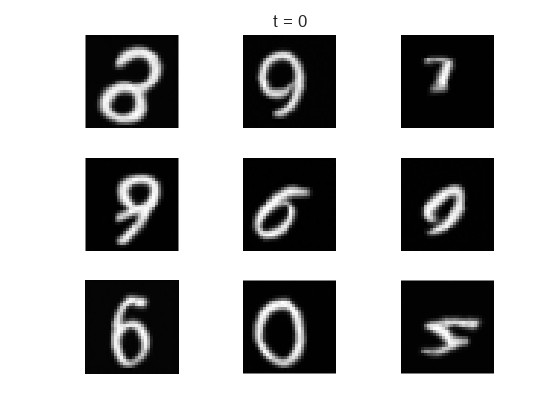

numImages = 9;
displayFrequency = 10;
figure
generatedImages = generateAndDisplayImages(net,varianceSchedule,imgSize,numImages,numInputChannels,displayFrequency);

## References

- Ho, Jonathan, Ajay Jain, and Pieter Abbeel. “Denoising Diffusion Probabilistic Models.” In *Advances in Neural Information Processing Systems*, 33:6840–51. Curran Associates, Inc., 2020. [https://proceedings.neurips.cc/paper_files/paper/2020/file/4c5bcfec8584af0d967f1ab10179ca4b-Paper.pdf](https://proceedings.neurips.cc/paper_files/paper/2020/file/4c5bcfec8584af0d967f1ab10179ca4b-Paper.pdf) 

- Ronneberger, O., P. Fischer, and T. Brox. "U-Net: Convolutional Networks for Biomedical Image Segmentation." *Medical Image Computing and Computer-Assisted Intervention (MICCAI)*. Vol. 9351, 2015, pp. 234–241.

## Supporting Functions

### Forward Noising Function

The forward noising function `applyNoiseToImage` takes as input an image `img`, a matrix of Gaussian noise `noiseToApply`, an integer `noiseStep` indicating the number of noise steps to apply to the image, and a variance schedule `varianceSchedule`, consisting of a vector of length `numNoiseSteps`.

At each step, the function applies random noise $\varepsilon$ drawn from a standard normal distribution to an image $x_t$ using the following formula:


$$x_{t + 1} = \sqrt{1 - \beta_t} x_t + \sqrt{\beta_t} \varepsilon.$$


To speed up the process of generating noisy images, use the following equation to apply multiple noising steps at once:


$$x_t = \sqrt{\bar{\alpha}_t} x_0 + \sqrt{1 - \bar{\alpha}_t} \varepsilon,$$


where $x_0$ is the original image and $\bar{\alpha}_t = \prod^t_{i = 1} (1 - \beta_i)$.

function noisyImg = applyNoiseToImage(img,noiseToApply,noiseStep,varianceSchedule)
alphaBar = cumprod(1 - varianceSchedule);
alphaBarT = dlarray(alphaBar(noiseStep),"CBSS");

noisyImg = sqrt(alphaBarT).*img + sqrt(1 - alphaBarT).*noiseToApply;
end

### Model Loss Function

The model loss function takes as input the DDPM network `net`, a mini-batch of noisy input images `X`, a mini-batch of noise step values `Y` corresponding to the amount of noise added to each image, and the corresponding target noise values `T`. The function returns the loss and the gradients of the loss with respect to the learnable parameters in `net`.

function [loss, gradients] = modelLoss(net,X,Y,T)
% Forward data through the network.
noisePrediction = forward(net,X,Y);

% Compute mean squared error loss between predicted noise and target.
loss = mse(noisePrediction,T);

gradients = dlgradient(loss,net.Learnables);
end

### Mini-batch Preprocessing Function

The `preprocessMiniBatch` function preprocesses the data using the following steps:

- Extract the image data from the incoming cell array and concatenate into a numeric array.

- Rescale the images to be in the range `[-1,1]`.

function X = preprocessMiniBatch(data)
% Concatenate mini-batch.
X = cat(4,data{:});

% Rescale the images so that the pixel values are in the range [-1 1].
X = rescale(X,-1,1,InputMin=0,InputMax=255);
end

### Image Generation Function

The `generateImages` function takes as input a trained DDPM network `net`, a variance schedule `varianceSchedule`, the image size `imageSize` and the number of desired images `numImages`. The function returns a batch of `numImages` images generated using the following reverse diffusion process:

- Generate a noisy image consisting of Gaussian random noise the same size as the desired image, drawn from a standard normal distribution.

- Use the network to predict the added noise $\varepsilon_\mathrm{pred}$.

- Remove this noise from the image using the formula:

$x_{t - 1} = \frac{1}\sqrt{1 - \beta_t} \left(x_t - \frac{\beta_t}{\sqrt{1 - \bar{\alpha}_t}} \varepsilon_\mathrm{pred} \right) + \sigma_t z$,

            where the posterior variance is $\sigma_t^2 = \frac{1 - \bar{\alpha}_{t-1}}{1 - \bar{\alpha}_t} \beta_t$, and $z$ is a different matrix of Gaussian random noise.

        4. Repeat steps 2-3 for each noise step, counting down from `numNoiseSteps` to `1`.

function images = generateAndDisplayImages(net,varianceSchedule,imageSize,numImages,numChannels,displayFrequency)
% Generate random noise.
images = randn([imageSize numChannels numImages]);

% Compute variance schedule parameters.
alphaBar = cumprod(1 - varianceSchedule);
alphaBarPrev = [1 alphaBar(1:end-1)];
posteriorVariance = varianceSchedule.*(1 - alphaBarPrev)./(1 - alphaBar);

% Reverse the diffusion process.
numNoiseSteps = length(varianceSchedule);

for noiseStep = numNoiseSteps:-1:1
    if noiseStep ~= 1
        z = randn([imageSize,numChannels,numImages]);
    else
        z = zeros([imageSize,numChannels,numImages]);
    end

    % Predict the noise using the network.
    predictedNoise = predict(net,images,noiseStep);

    sqrtOneMinusBeta = sqrt(1 - varianceSchedule(noiseStep));
    addedNoise = sqrt(posteriorVariance(noiseStep))*z;
    predNoise = varianceSchedule(noiseStep)*predictedNoise/sqrt(1 - alphaBar(noiseStep));

    images = 1/sqrtOneMinusBeta*(images - predNoise) + addedNoise;

    % Display intermediate images.
    if mod(noiseStep,displayFrequency) == 0
        tLay = tiledlayout("flow");
        title(tLay,"t = "+ noiseStep)
        for ii = 1:numImages
            nexttile
            imshow(images(:,:,:,ii),[])
        end
        drawnow
    end
end

% Display final images.
tLay = tiledlayout("flow");
title(tLay,"t = 0")
for ii = 1:numImages
    nexttile
    imshow(images(:,:,:,ii),[])
end
end

*Copyright 2023 The MathWorks, Inc.*